# Plantilla problema práctica 1 Model. Exp.

Es necesario cargar los datos suministrados por la empresa en este punto

load data2.mat

## Petición de la empresa

Cordial saludo ingenieros matemáticos. Nos comunicamos con ustedes porque necesitamos determinar un modelo para el comportamiento de cierta planta ultra secreta. Como podrán comprender, nos vemos en la obligación de reservarnos la mayor cantidad de información posible. Nosotros mismos ya hemos adelantado parte de los procesos necesarios para determinar el modelo. Sabemos que nuestra planta consta de una única entrada y una única salida, la entrada tiene un valor de 1000 unidades regularmente y la planta se mantiene en estado estacionario. Partiendo de este punto de estabilidad, nuestro anterior ingeniero varió el valor de la entrada en un rango de 500 a 1500 tal y como pueden ver a continuación

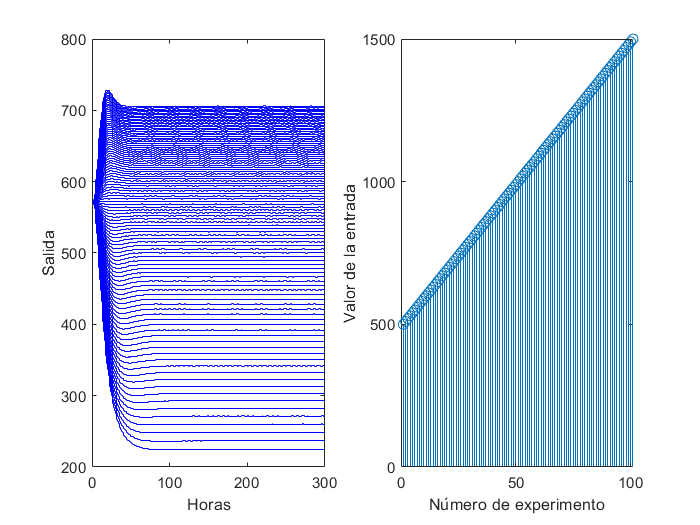

figure(1)
clf
subplot(1,2,1)
stairs(0:300,y_sample','b')
xlabel('Horas')
ylabel('Salida')
subplot(1,2,2)
stem(u_lineal)
xlabel('Número de experimento')
ylabel('Valor de la entrada')

Esta información se las compartimos a través de la matriz **y_sample** y el vector **u_lineal**. La primera fila de la matriz corresponde con el primer valor del vector como entrada. Para cada caso, se tomaron muestras del estado del sistema cada hora y esperamos hasta que el sistema se estabilizara. Luego, para un solo experimento, se aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de 1000 a 1120 de forma abrupta. Los datos de la respuesta del modelo se presentan a continuación

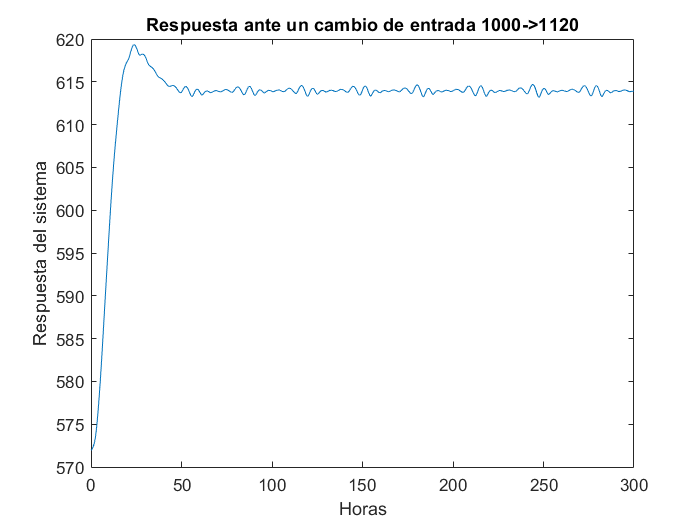

figure
clf
plot(t,y_response)
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

Primero escalamos la respuesta para que inicie en 0. Con estos datos calculamos el tiempo de muestreo.

aux = y_response - y_response(1);

Calculamos el valor de estabilización $y_{\mathrm{ss}}$ mediante la mediana de los últimos valores (debido a que vemos que hay una oscilación en estado estacionario). Calculamos $t_r$ como el tiempo que toma ir desde el 10% del valor de estabilización hasta el 90% del valor de estabilización

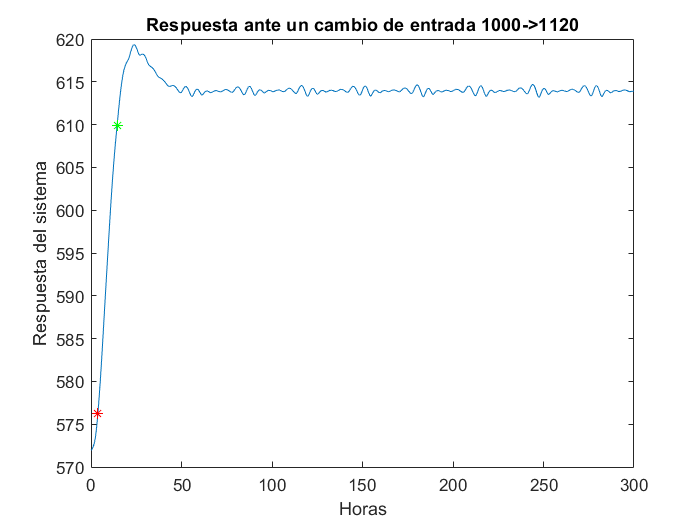

k = median(aux(1500:end));
in = find(aux >= 0.1*k,1);
fin = find(aux >= 0.9*k,1);
 tr = t(fin) - t(in);
figure
clf
plot(t,y_response)
hold on;
plot(t(in),y_response(in),'r*')
plot(t(fin),y_response(fin),'g*')
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

ts = round(tr/10) %criterio para determinar tiempo de muestreo

ts = 1

Con base en dicha información, nuestro anterior ingeniero decidió excitar el sistema con un periodo de muestreo de 1 hora y una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120 para luego proceder a identificar un modelo apropiado para la planta, sin embargo, tuvimos que prescindir del ingeniero en este punto y el sistema no ha podido identificarse. Los datos recopilados se muestran a continuación

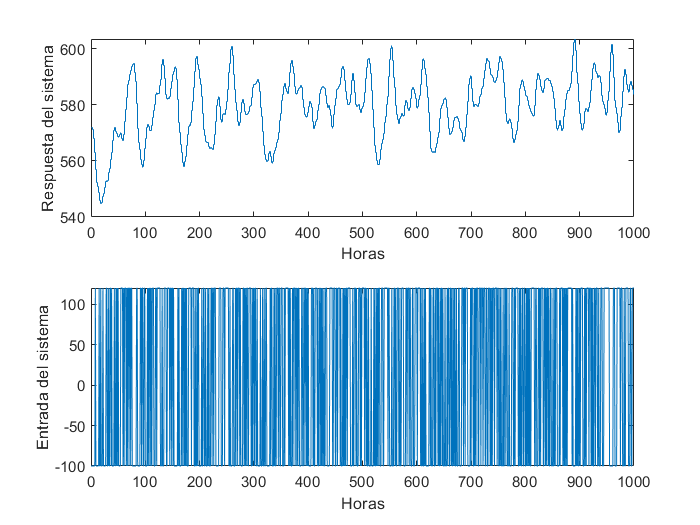

figure(3)
clf
subplot(2,1,1)
stairs(0:1000,y')
xlabel('Horas')
ylabel('Respuesta del sistema')
subplot(2,1,2)
plot(0:1000,u)
xlabel('Horas')
ylabel('Entrada del sistema')

Nos hemos contactado con ustedes con la esperanza de que puedan evaluar la metodología que siguió nuestro anterior ingeniero (si es adecuada o si modificarían algo) y, en caso de que lo consideren posible, concluir el proceso de identificación del sistema. Les solicitamos el mayor detalle posible en sus respuestas así como en la justificación de porqué deberíamos confiar o no en el modelo que ustedes puedan identificar. Estaremos muy atentos. 

m_sample = median(y_sample(:,150:end),2);
clf
plot(u_lineal',m_sample)
hold on;
line([900 900],[200 800])
line([1120 1120],[200 800])
x1 = 900;
y1 = interp1(u_lineal,m_sample,x1);
x2 = 1120;
y2 = interp1(u_lineal,m_sample,x2);
m = (y2-y1)/(x2-x1);
y_line = m*(u_lineal - x2) + y2

y_line =   376.9860  380.8077  384.6293  388.4510  392.2727  396.0944  399.9161  403.7378  407.5595  411.3812  415.2029  419.0245  422.8462  426.6679  430.4896  434.3113  438.1330  441.9547  445.7764  449.5981  453.4197  457.2414  461.0631  464.8848  468.7065  472.5282  476.3499  480.1716  483.9933  487.8149  491.6366  495.4583  499.2800  503.1017  506.9234  510.7451  514.5668  518.3885  522.2101  526.0318  529.8535  533.6752  537.4969  541.3186  545.1403  548.9620  552.7837  556.6053  560.4270  564.2487


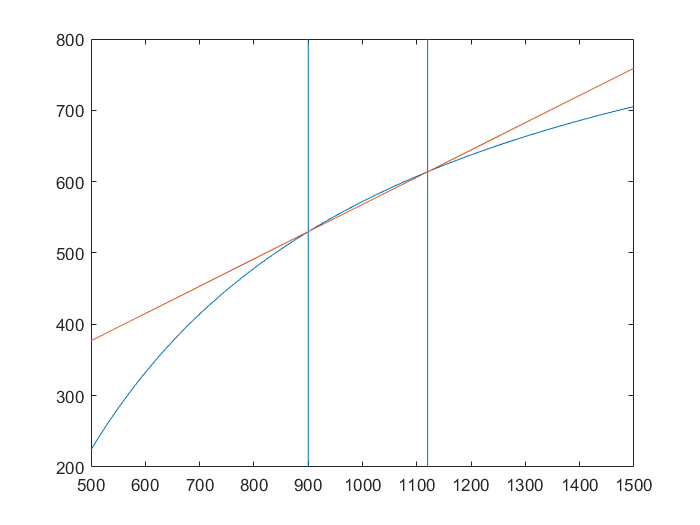

plot(u_lineal,y_line)

En la figura anterior se graficó la mediana de los últimos valores de y_sample (para tener una idea del valor de estabilización ) contra la entrada u_lineal. Se puede observar que en el rango de valores escogidos para la PBRS (900 a 1120), los valores aproximados de estabilización se comportan casi linealmente. 

Suponemos que el ingeniero escogió los valores de 900 a 1120 porque en esta región hay un comportamiento casi lineal y buscó que los valores estuviesen alrededor del punto de equilibrio en el que la empresa trabaja normalmente.

Primero calculamos el orden de excitación persistente. De este cálculo observamos que tendríamos problemas al ajustar modelos de orden mayor a 25 puesto que necesitamos que el orden de excitación persistente sea al menos 2m

pexcit(iddata(y,u',1))

ans = 50

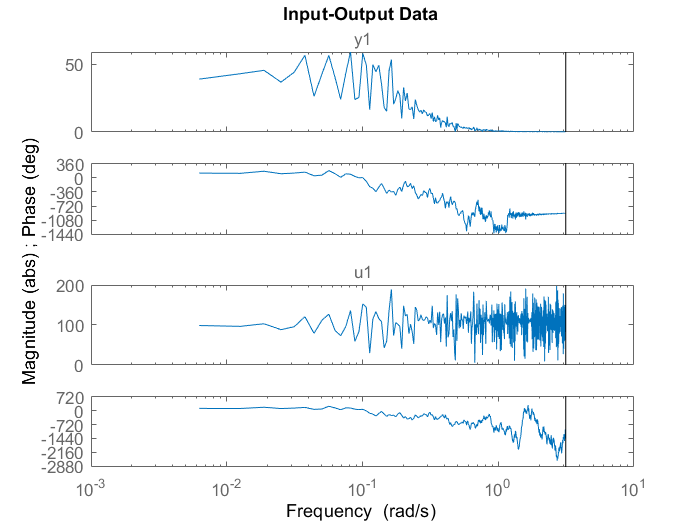

Data  = fft(iddata(y,u',1));
plot(Data)

## Exploración de los datos

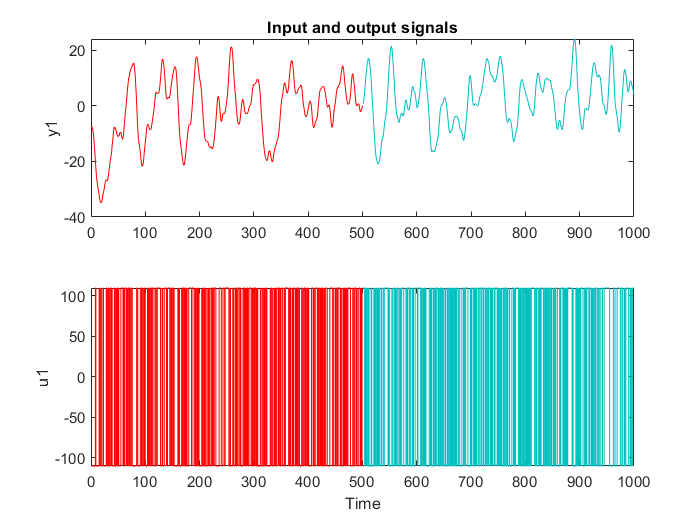

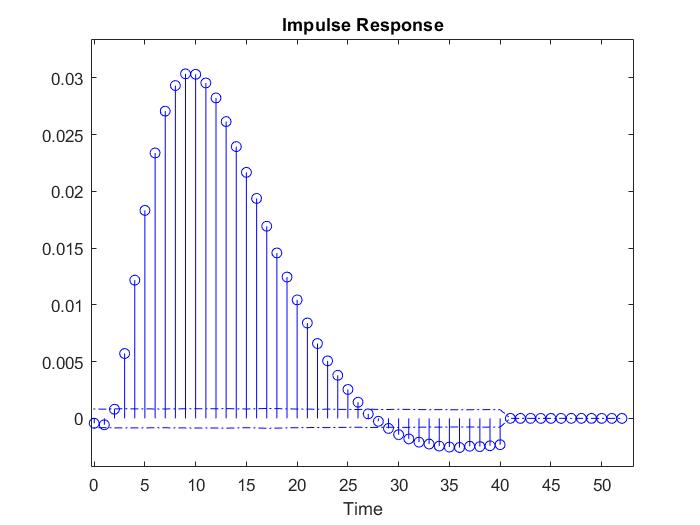

En la gráfica de respuesta al impulso podemos observar que hay dos datos al inicio dentro del intervalo de confianza (al 99%)  y un dato justo en el límite de dicho intervalo por lo que intuimos que el retardo estaría a 2 o 3 unidades de tiempo.

Estimamos el retardo mediante la función delayest,

delayest(data2de)

ans = 3

Graficamos la respuesta a la frecuencia.

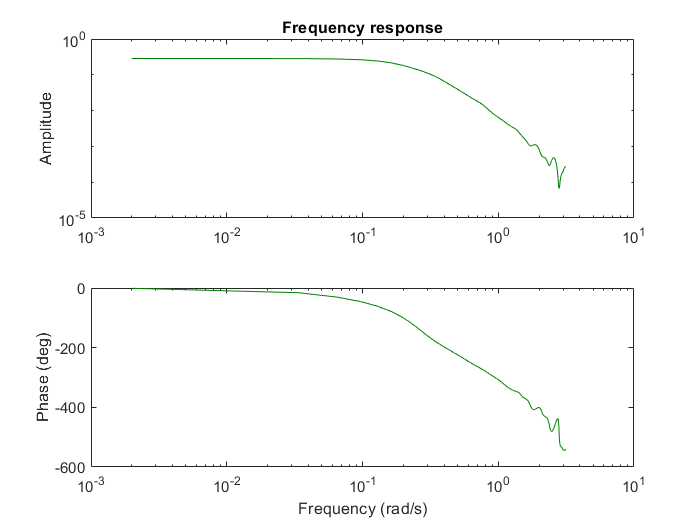

Al final no se ve mucho ruido entonces no hay necesidad de filtrar y vemos que la elección de la PBRS fue relativamente buena.

advice(data2de)                       

General data characteristics:
-----------------------------
This is a time domain data set with 1 input(s) and 1 output(s), 501 samples and 
1 experiment(s).

All inputs in the data have been denoted as 'zero order hold' ('zoh'), i.e. 
they are assumed to be piecewise constant over the sample time.
If the input is a sampled continuous signal and you plan to build or convert to 
continuous-time models, it is recommended to mark the InterSample property as 
'First order hold': Data.InterSample = 'foh' or Data.int = {'foh','foh', ...} 
for multi-input signals.

Excitation level in data:
-------------------------
The input is persistently exciting of order 50. This means that you will 
encounter problems if estimating models of order higher than 50.

Possibility of feedback in data:
--------------------------------
There is a strong indication of feedback in data.
You should be careful when interpreting the results of SPA and also interpret 
the results of output error models with care (Ou

Modelo lineal, Hay feedback, recomienda un box jenkins

## Ajuste de modelos

Iniciamos explorando modelos ARX, considerando un grupo grande de modelos, fijando $\mathrm{nk}=3$ 

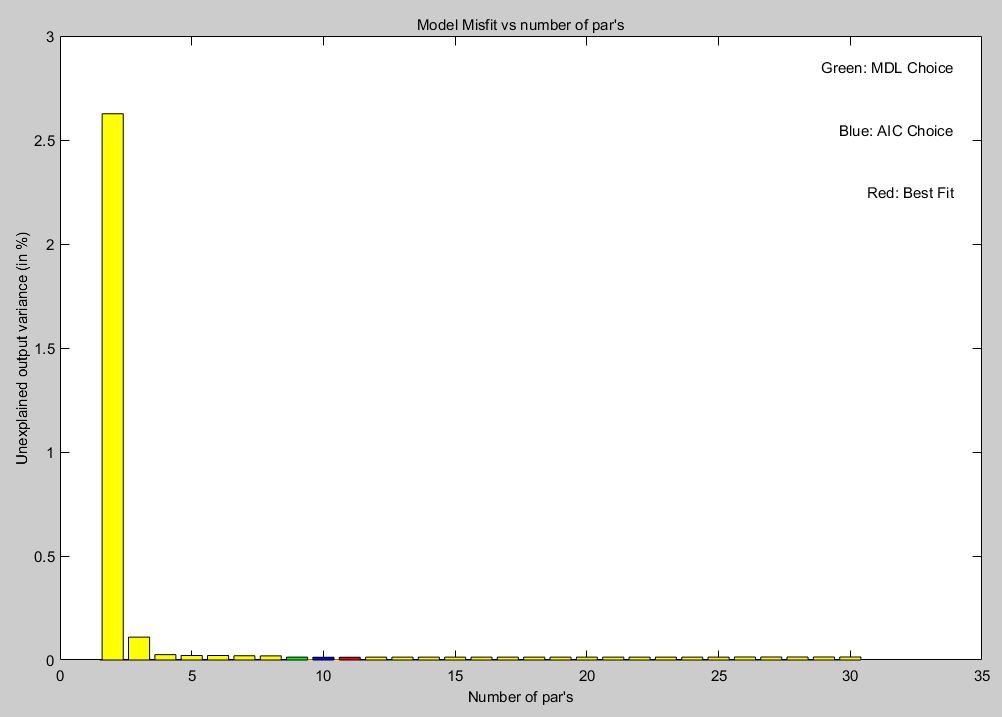

Los modelos según los criterios de la gráfica son:

- Criterio MDL: ARX543

- Criterio AIC: ARX643

- Best fit: ARX 653

Escogemos el modelo ARX543 que recomienda el criterio MDL (siguiendo el criterio de parsimonia).

A continuación se muestra el análisis de los residuos para el modelo ARX543. Es claro que en la correlación cruzada hay un pico abrupto por lo que tenemos indicios de que faltan ceros o no se ha estimado bien el retardo.

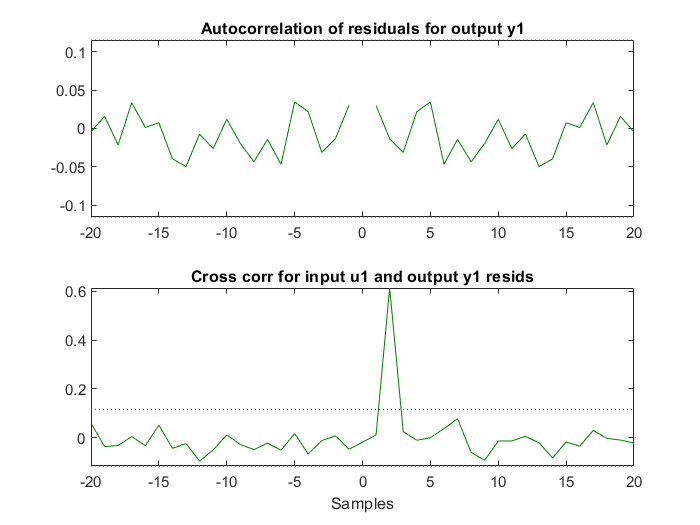

Para identificar si el problema es la falta de ceros o que se ha estimado mal el retardo, amentamos el número de ceros ($\mathrm{nb}$) y escogemos el modelo ARX643 (el modelo que recomienda el criterio AIC). Vemos en la siguiente figura que el modelo ARX643 (azúl claro) presenta el mismo problema que el modelo ARX543 (verde) por lo que concluímos que al aumentar el número de ceros el modelo sigue fallando. Por tanto, es probable que se esté estimando erróneamente el retardo.

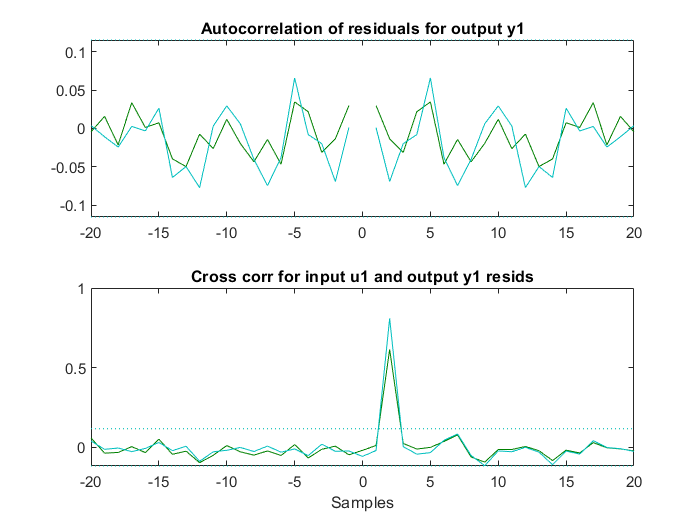

Volvemos a explorar un conjunto grande de modelos ARX, esta vez con retardo $\mathrm{nk}=2$

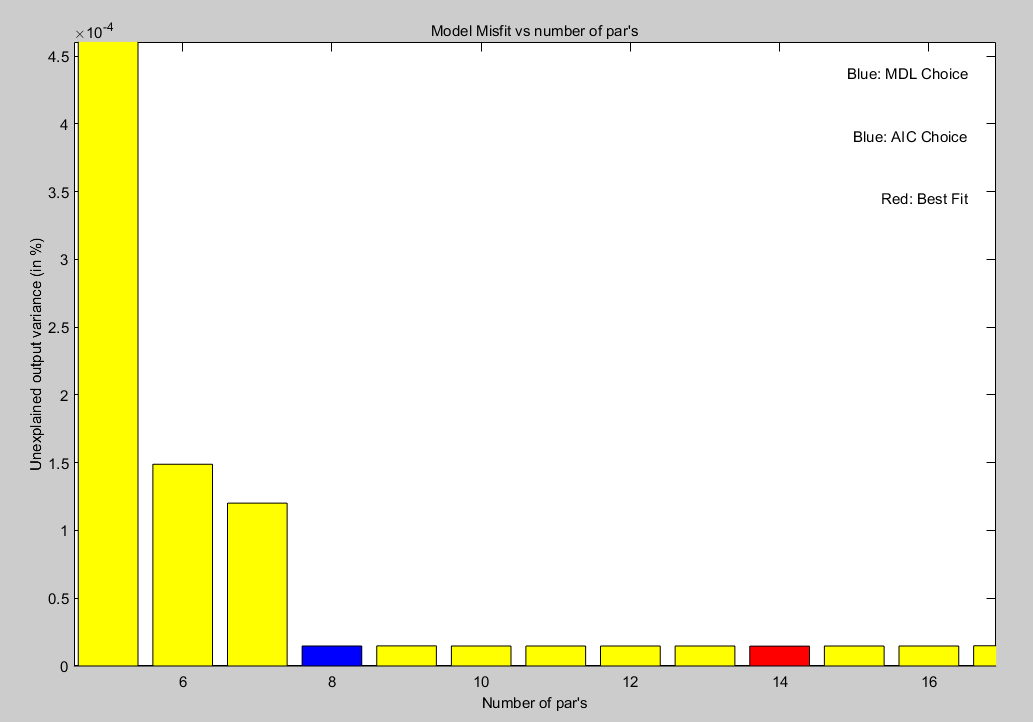

Los modelos recomendados según los criterios de la gráfica son:

- Criterio MDL/AIC :ARX 442

- Criterio Best fit: ARX 772

En la siguiente gráfica se muestra el análisis residual para los modelos ARX 442 y el modelo ARX 772. Ambos tienen el mismo pico abrupto que de nuevo, nos da indicios de que el retardo está mal estimado o se necesitan más ceros. Nótese que el modelo ARX 772 también presenta el mismo problema. Es decir, se aumentaron ceros y el modelo sigue fallando. Por tanto, concluímos que en estos modelos también se ha estimado mal el retardo.

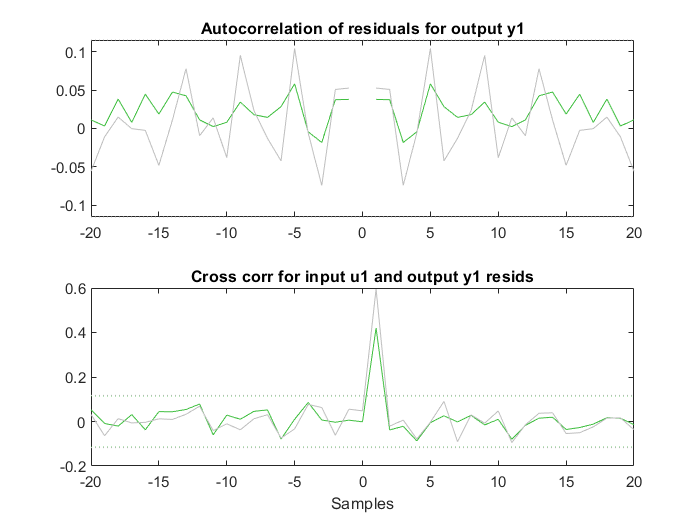

Exploramos ahora modelos ARX con retardo 1

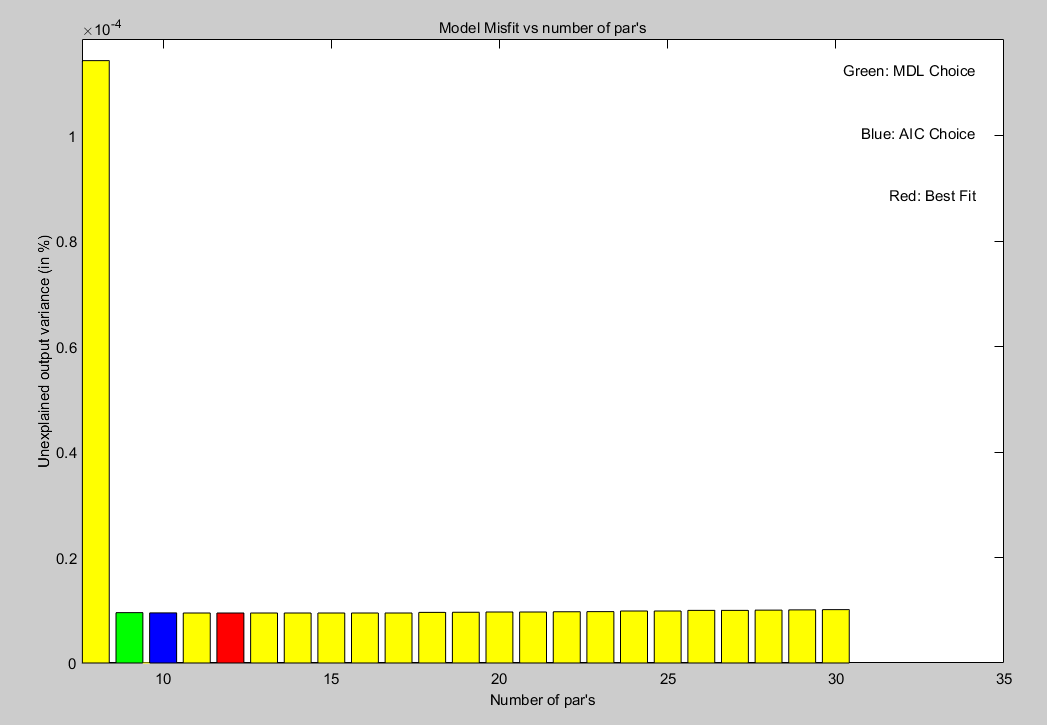

Los modelos recomendados según los criterios de la gráfica son:

- Criterio MDL :ARX 451

- Criterio AIC : ARX 551

- Criterio Best fit: ARX 661

Seleccionamos el Arx 451 según el criterio MDL. 

En la siguiente figura se muestra la autocorrelación y la correlación cruzada de los residuos.

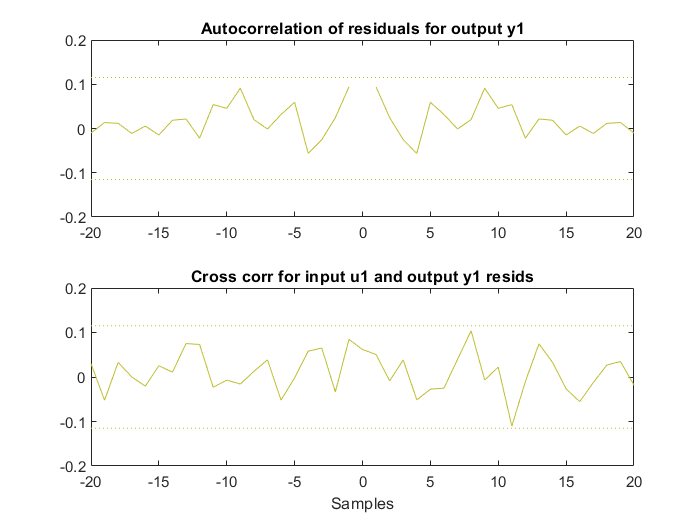

Se puede ver que la autocorrelación y la correlación cruzada están dentro de los intervalos de confianza (99%). Esto significa que esta elección del modelo pasa el test de blancura, lo que indicaría que el modelo es capaz de explicar la salida.

La siguiente figura muestra una comparación entre el modelo Arx 451, el modelo obtenido con el método de correlaciones y los datos originales, se observa un buen ajuste. El modelo ARX tiene un r2 de 94.77 mientras el obtenido con le método de correlacion es de 92.62.

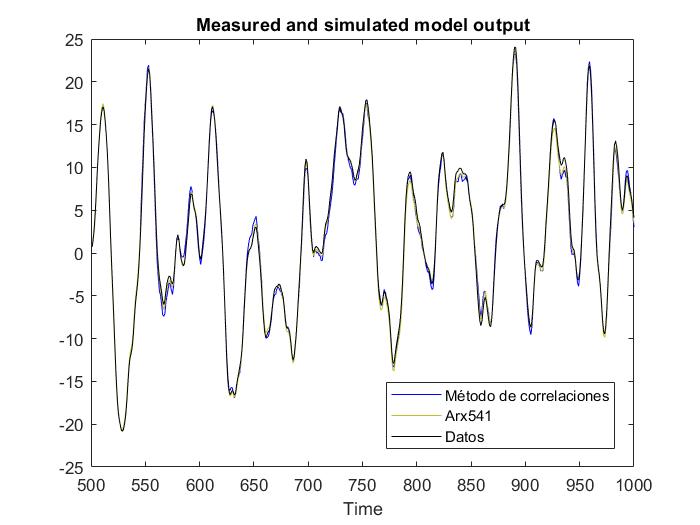

El siguiente gráfico de respuesta a la frecuencia compara el modelo ARX541 seleccionado con el modelo espectral SPA y se puede observar que hay un ajuste relativamente bueno (es menos bueno en las menores frecuencias).

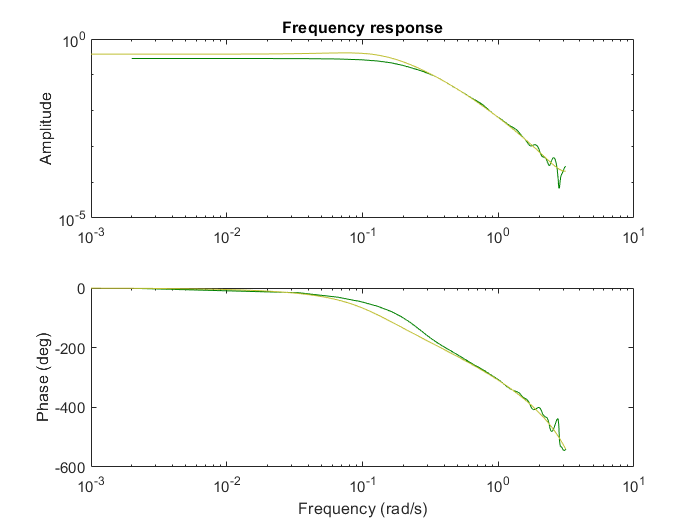

En la gráfica de la respuesta temporal se puede observar que el ajuste es muy bueno al inicio pero el ajuste es menos bueno a partir de $t=15$

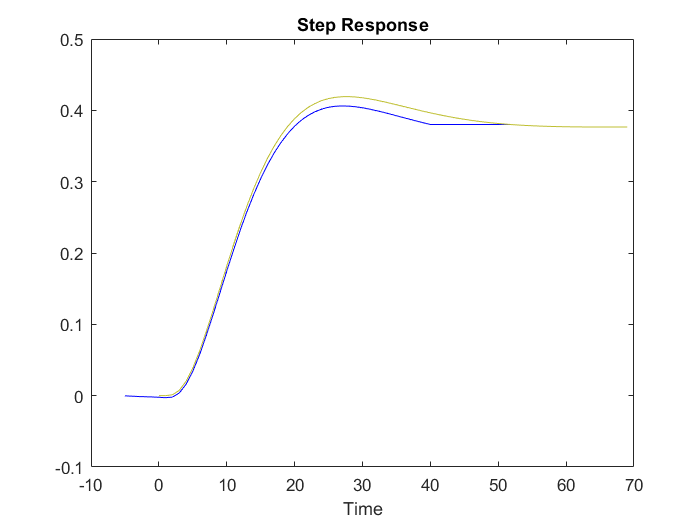

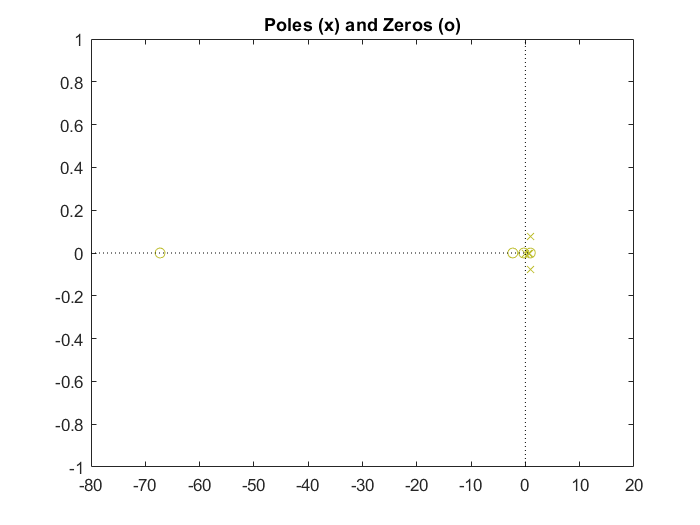

Modelo Arx 451:


$$A\left(z\right)=1+a_1 z^{-1} +a_2 z^{-2} +a_3 z^{-3} +a_4 z^{-4}$$



$$B\left(z\right)=b_1 z^{-1} +b_2 z^{-2} +b_3 z^{-3} +b_4 z^{-4} +b_5 z^{-5}$$


donde


$$a_1 =-3\ldotp 196\pm 9\ldotp 8\times \;{10}^{-3} \left(0\ldotp 31%\right)$$



$$a_2 =\;3\ldotp 801\pm 2\ldotp 2\times \;{10}^{-2} \left(0\ldotp 58%\right)$$



$$a_3 =-1\ldotp 99\pm 1\ldotp 7\times \;{10}^{-2} \left(0\ldotp 85%\right)$$



$$a_4 =\;0\ldotp 386\pm 4\times \;{10}^{-3} \left(1\ldotp 0%\right)$$



$$b_1 =1\ldotp 789\times \;{10}^{-5} \pm 1\ldotp 2\times \;{10}^{-6} \left(6\ldotp 7%\right)$$



$$b_2 =\;0\ldotp 001235\pm 1\ldotp 2\times \;{10}^{-6} \left(0\ldotp 1%\right)$$



$$b_3 =0\ldotp 002045\pm 1\ldotp 2\times \;{10}^{-5} \left(0\ldotp 61%\right)$$



$$b_3 =0\ldotp 002044\pm 3\ldotp 2\times \;{10}^{-5} \left(1\ldotp 55%\right)$$



$$b_5 =\;-0\ldotp 0007933\pm 9\ldotp 2\times \;{10}^{-6} \left(1\ldotp 16%\right)$$


arx451 =                                                                      

Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                           

  A(z) = 1 - 3.196 (+/- 0.009857) z^-1 + 3.801 (+/- 0.02237) z^-2             

                 - 1.99 (+/- 0.01665) z^-3 + 0.386 (+/- 0.004008) z^-4        

  B(z) = 1.789e-05 (+/- 1.185e-06) z^-1 + 0.001235 (+/- 1.2e-06) z^-2         

          + 0.002045 (+/- 1.242e-05) z^-3 - 0.002044 (+/- 3.165e-05) z^       

                                   -4 - 0.0007933 (+/- 9.241e-06) z^-5        

Name: arx451                                                                  

Sample time: 1 seconds                                                        

Parameterization:                                                             

   Polynomial orders:   na=4   nb=5   nk=1                                    

   Number of free coefficients: 9                                             

   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

## Respuesta a la empresa

A continuación desarrolle lo que la empresa le ha pedido.